# Fit of Q-band data at 0.1 mW power

clearvars; close all
% Path to the project folder
chdir('D:\Profile\qse\files\projects\sijia_sulphurization');
% Add source file directory
addpath(genpath('scr'));

## Import

% Load directory with the raw files
load('data/processed/gm20230622_sample4_Qband_mwpw.mat');

# Fit

Not enough resolution to fit the spin systems. Multifrequency will help in this regard.

ICW = 5;
Sys0 = struct('g', 2.0046, ...
    'lwpp', [0. 1.1239]);
Sys1 = struct('g', 2.003, ...
    'lwpp', [0.8397 0.], ...
    'weight', 2.6355e-5);

Vary0 = struct('g', .005, ...
    'lwpp', Sys0.lwpp);
Vary1 = struct('g', .005, ...
    'lwpp', Sys1.lwpp, ...
    'weight', 1);


Exp.Range = [min(cw(ICW).x) max(cw(ICW).x)];
Exp.mwFreq = cw(ICW).Params.MWFQ*1e-9;
Exp.nPoints = numel(cw(ICW).x);


MaskL = 1:numel(cw(ICW).x) < 195;
MaskR = 1:numel(cw(ICW).x) > 378;
Mask = logical(MaskL + MaskR);
FitOpt.mask = Mask;

Sys = {Sys0, Sys1};
SysVary = {Vary0, Vary1};

% Fit = esfit(yy, @pepper, {{Sys1, Sys2, Sys3}, Exp}, {{Vary1, Vary2, Vary3}}, FitOpt)
Fit = esfit(-real(cw(ICW).y2), @pepper, {Sys, Exp}, {SysVary}, FitOpt);

-- esfit ------------------------------------------------
Data size:                [1024, 1]
Model function name:      pepper
Number of fit parameters: 5
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 5 active parameters...
iteration   1: value 1.05569e+00   edge 1.00000e-01   initial simplex
iteration   2: value 1.05569e+00   edge 2.24780e-01   contraction inside
iteration   3: value 1.05569e+00   edge 2.24780e-01   contraction inside
iteration   4: value 1.05569e+00   edge 2.24780e-01   contraction inside
iteration   5: value 1.05569e+00   edge 2.24780e-01   contraction inside
iteration   6: value 1.05569e+00   edge 2.24780e-01   contraction inside
iteration   7: value 1.05569e+00   edge 2.24780e-01   contraction inside
iteration   8: value 1.05569e+00   edge 2.24780e-01   contraction inside
iteration   9: value 1.05569e+00   

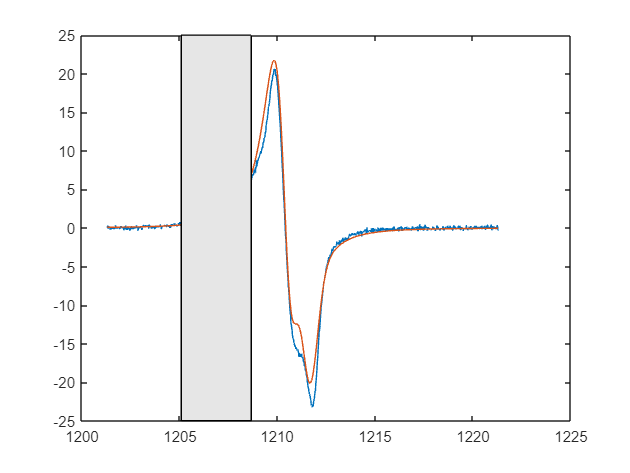

Dir.SPath = 'data/processed/gm20230622_sample4_Qband_mwpw_18dB_fit.mat';
Title = '2023-06-22 sample 4 Qband mwpw 18dB fit';
save(Dir.SPath, 'Fit', 'Title');